# *E.coli *(iJO1366) "Arginine and Proline Metabolism" Subsystem

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Arginine and Proline Metabolism" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1. Arginine and Proline Metabolism Subsystem**

The reactions associated with the "Arginine and Proline Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
arginineProlineSubSystems = {'Arginine and Proline Metabolism'};
arginineProlineReactions = model.rxns(ismember(model.subSystems,arginineProlineSubSystems));
[tmp,arginineProline_rxnID] = ismember(arginineProlineReactions,model.rxns);
reactionNames = model.rxnNames(arginineProline_rxnID);
reactionFormulas = printRxnFormula(model,arginineProlineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',arginineProlineReactions)

T = 40×2 table
                                     reactionNames                                                           reactionFormulas                                  
                 ______________________________________________________    ____________________________________________________________________________________

    ABTA         '4-aminobutyrate transaminase'                            '4abut_c + akg_c  -> glu__L_c + sucsal_c '                                          
    ABUTD        'Aminobutyraldehyde dehydrogenase'                        '4abutn_c + h2o_c + nad_c  -> 4abut_c + 2 h_c + nadh_c '                            
    ACGK         'Acetylglutamate kinase'                                  'acglu_c + atp_c  -> acg5p_c + adp_c '                                              
    ACGS         'N-acetylglutamate synthase'   

A Escher [3] map of this  "Arginine and Proline Metabolism" subsystem is shown below (Glycine_ Serine_Metabolism_Subsystem.json).

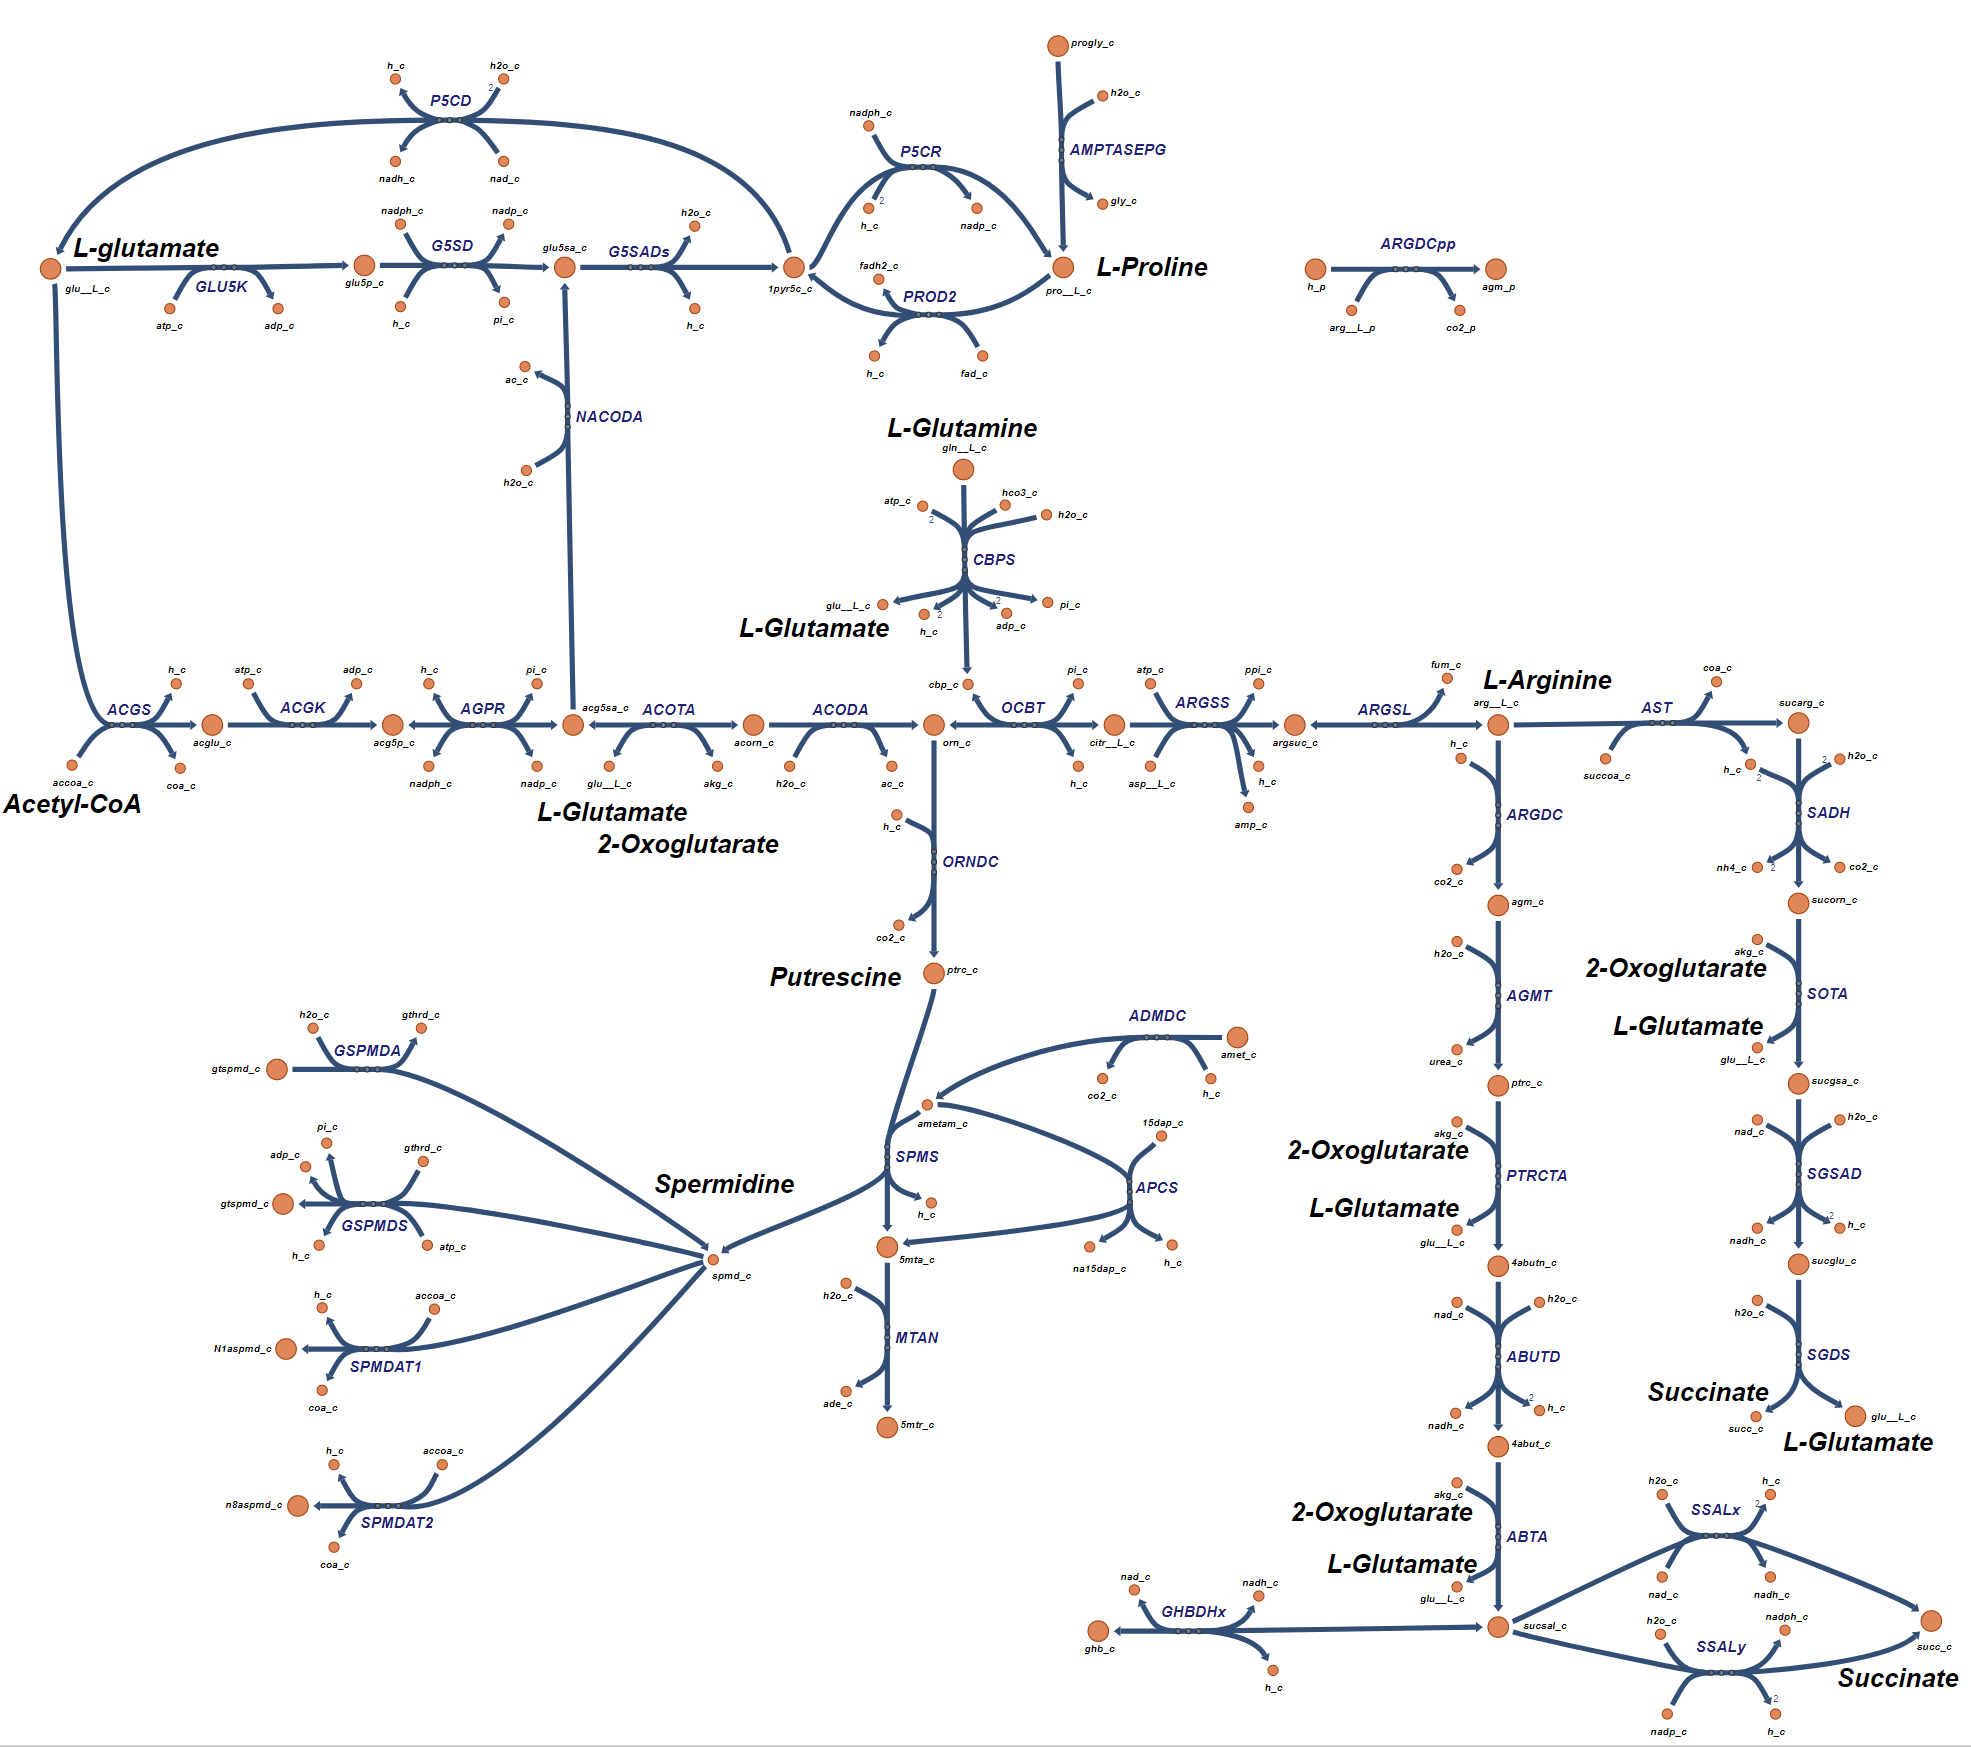

**Figure xx.** "Arginine and Proline Metabolism" subsystem which includes Putrescine and Spermidine biosynthesis pathways.

This subsystem also include the biosynthesis pathways for Putrescine and Spermidine. Putrescine ('ptrc_c') and Spermidine ('spmd_c') are precursors to polyamines. This subsystem also includes the pathways that can be used to convert L-Arginine ('arg__L_c') to L-Glutamate ('glu__L_c') and Succinate ('succ_c').

Let's look at the active reactions in the "Arginine and Proline Metabolism" subsystem due to an aerobic response. 

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(arginineProlineReactions, round(FBAsolution.x(arginineProline_rxnID),3))

ABTA	0	
ABUTD	0	
ACGK	0.291	
ACGS	0.291	
ACODA	0.291	
ACOTA	-0.291	
ADMDC	0	
AGMT	0	
AGPR	-0.291	
AMPTASEPG	0	
APCS	0	
ARGDC	0	
ARGDCpp	0	
ARGSL	0.291	
ARGSS	0.291	
AST	0	
CBPS	0	
G5SADs	0.217	
G5SD	0.217	
GHBDHx	0	
GLU5K	0.217	
GSPMDA	0	
GSPMDS	0	
MTAN	0	
NACODA	0	
OCBT	0.291	
ORNDC	0	
P5CD	0	
P5CR	0.217	
PROD2	0	
PTRCTA	0	
SADH	0	
SGDS	0	
SGSAD	0	
SOTA	0	
SPMDAT1	0	
SPMDAT2	0	
SPMS	0	
SSALx	0	
SSALy	0	


From this it can be seen that the primary L-Arginine begins with L-Glutamate and is composed of the following reactions; 'ACGS', 'ACGK', 'AGPR', 'ACOTA', 'ACODA', 'OCBT', 'ARGSS', and 'ARGSL'. These are the reaction sthat have the flux value of +/- 0.291.On the other hand, the primary L-Proline pathway starts with L-Glutamate and is composed of the following reactions; 'GLU5K', 'G5SD', 'G5SADs', and 'P5CR'. These are the reaction sthat have the flux value of +/- 0.217. 

Below is an Escher [3] figure of the "Arginine and Proline Metabolism"subsystem in an aerobic condition using xxx as the data file.

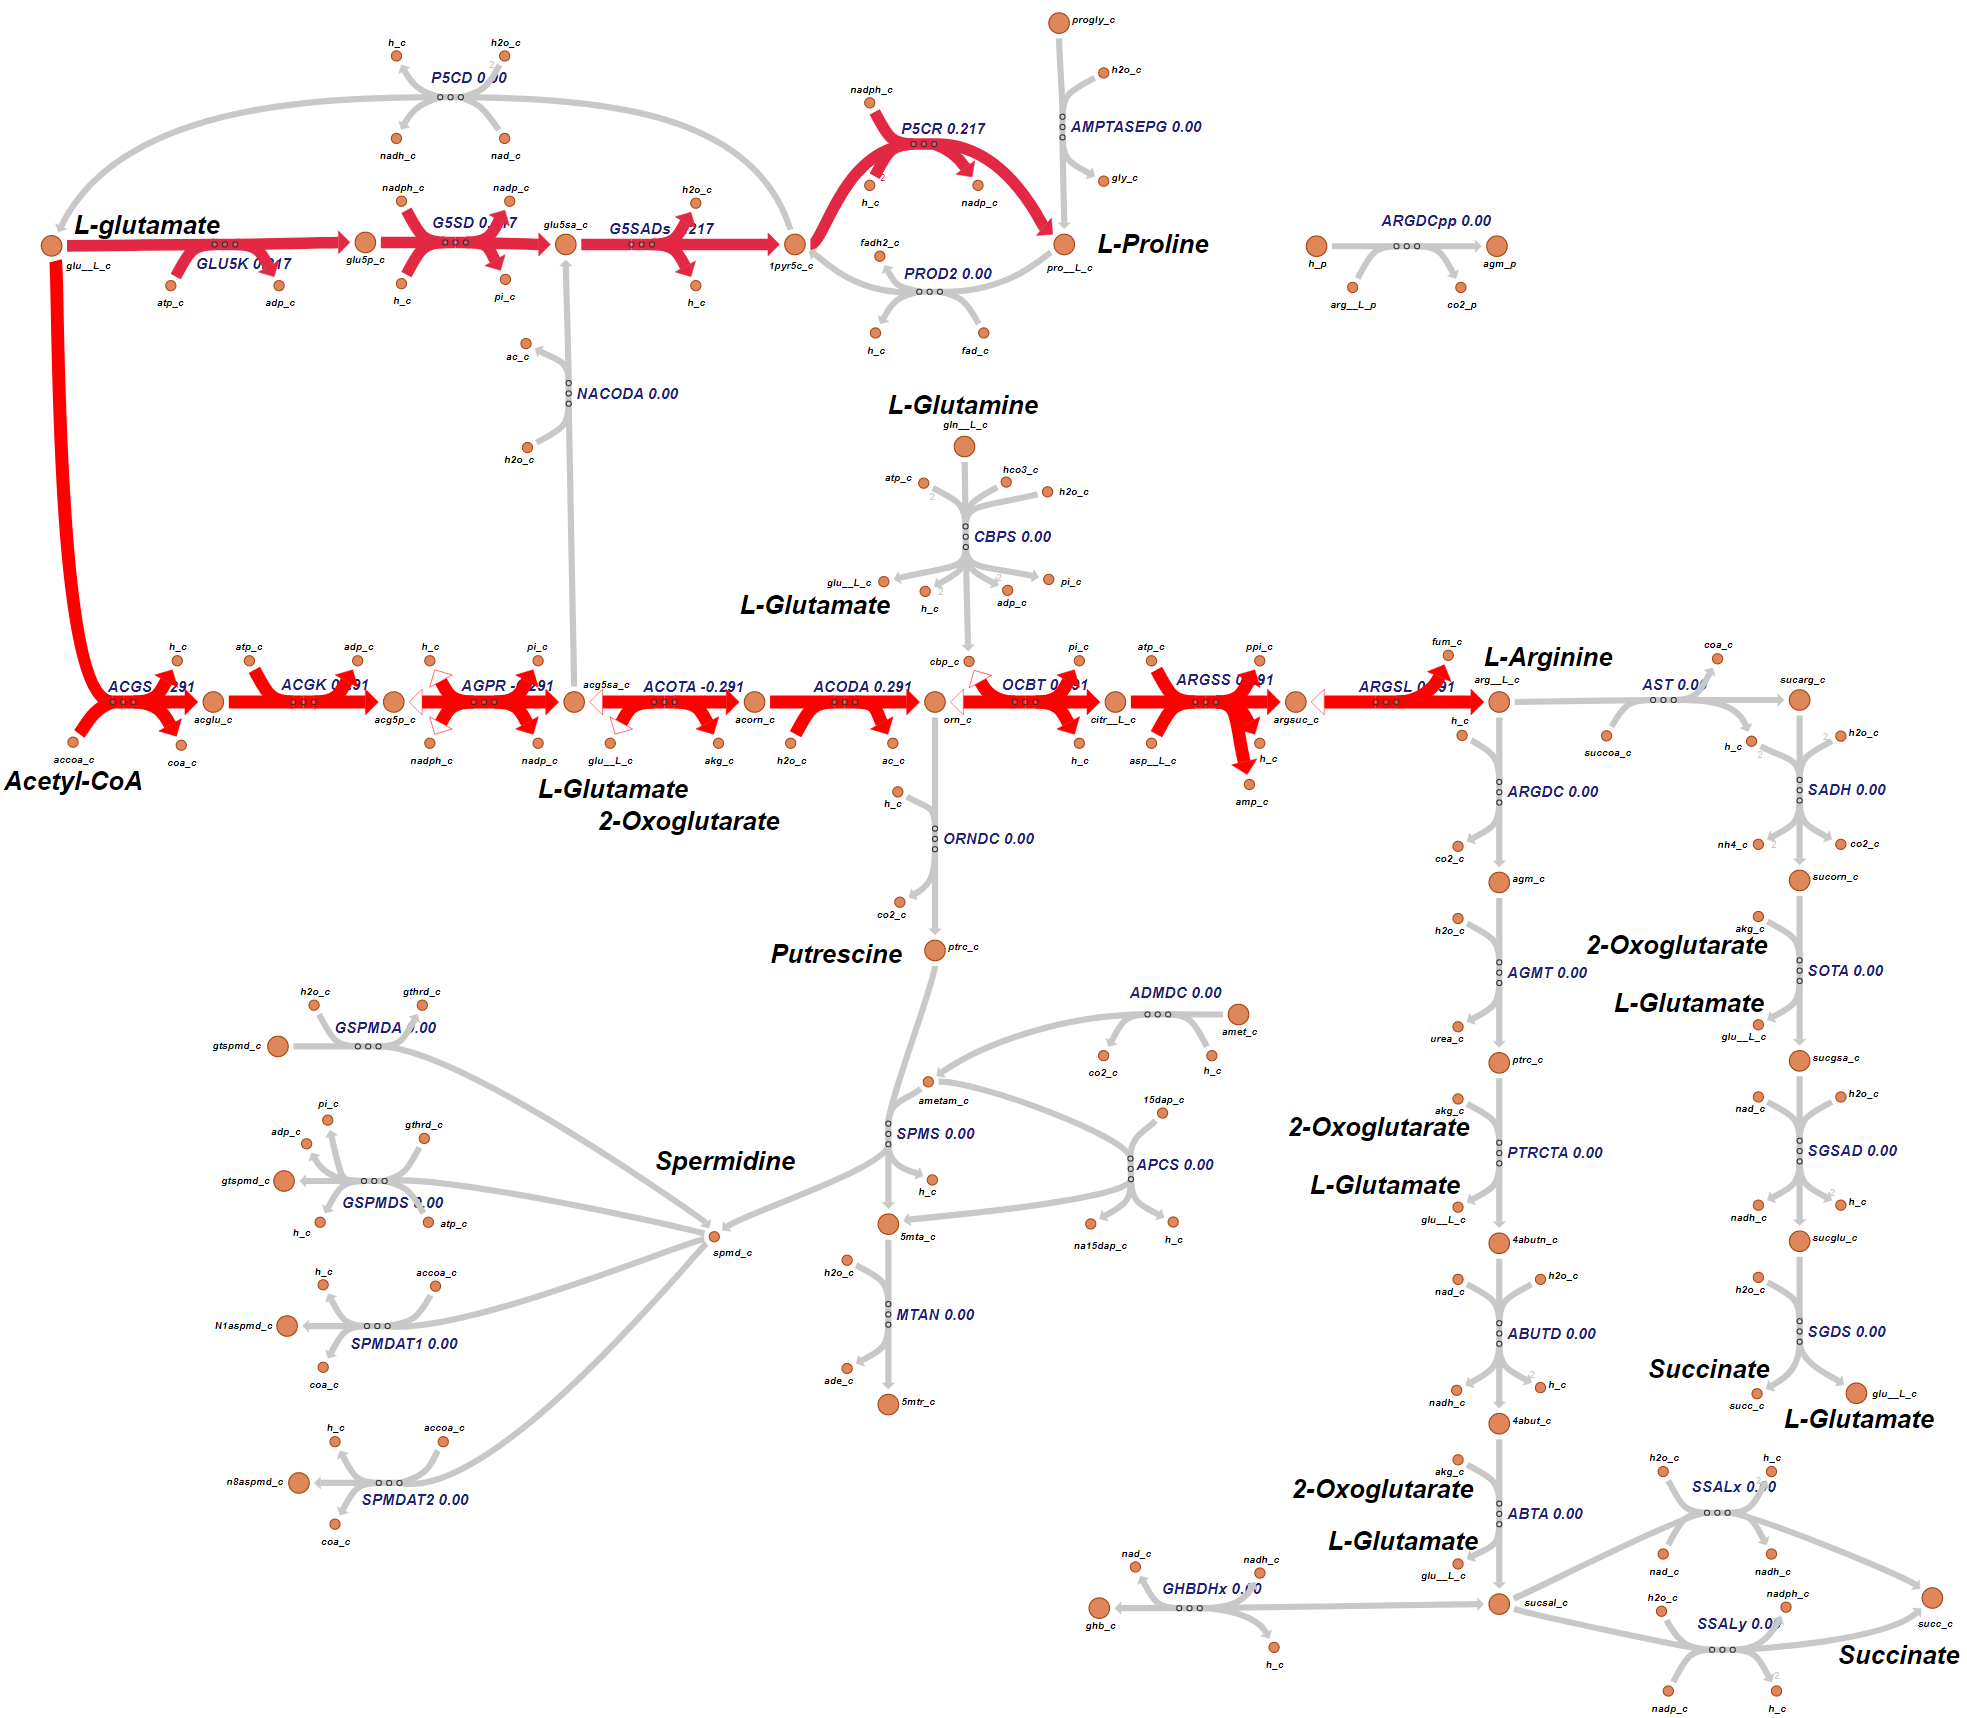

Figure xx. "Arginine and Proline Metabolism"

**L-Proline**

Let's begin by identifying the reactons that dierctly produce L-Proline.

surfNet(model, 'pro__L_c')


Met #834  pro__L_c, L-Proline, C5H9NO2
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

The reactions that directly produce L-Proline include 'AMPTASEPG', 'P5CR', 'PROabcpp', 'PROt2rpp', and 'PROt4pp', and 'PROGLYabcpp'.  The first reaction ('AMPTASEPG') converts L-Prolinylglycine to L-Proline. The second reaction ('P5CR') is the final reaction in the primary pathway from L-Glutamate to L-Proline. The transporter reactions ('PROabcpp', 'PROt2rpp', and 'PROt4pp') associated allow the transport of L-Proline between the periplasm and the cytoplasm.  The first of these transporters is an ABC transporter that requires ATP. The second trasnporter rquires energy from teh protonmotice force, while the third reaction is a sodium/L-Proline symporter. L-Proline is allows to diffuse from the extracellular space to the periplasm through the reaction 'PROtex'. The final reaction is an ABC transporter that moves L-Prolinylglycine from the periplasm to the cytoplasm.  L-Prolinylglycine is diffuses from the extracellular space to the periplasm through the reaction 'PROGLYtex'.

Now let's follow the primary pathway from L-Proline to see if there are any other duplicate pathways for the production of L-Proline. Lets start by identifying the connections to 'P5CR'.

surfNet(model, 'P5CR')


Rxn #2015  P5CR, Pyrroline-5-carboxylate reductase   Bd: 0 / 1000
1pyr5c_c + 2 h_c + nadph_c -> nadp_c + pro__L_c  
  id    Met       Stoich     Name, Formula
Reactant:
 #20    1pyr5c_c  -1         1-Pyrroline-5-carboxylate, C5H6NO2
 #577        h_c  -2         H+, H
 #723    nadph_c  -1         Nicotinamide adenine dinucleotide phosphate - reduced, C21H26N7O17P3
Product:
 #722     nadp_c  1          Nicotinamide aden

The active metabolite in this pathway is '1pyr5c_c' (1-Pyrroline-5-carboxylate), let's find the reaction that produce it. 

surfNet(model, '1pyr5c_c')


Met #20  1pyr5c_c, 1-Pyrroline-5-carboxylate, C5H6NO2
Consuming reactions:
#2014  P5CD  1-pyrroline-5-carboxylate dehydrogenase  
  1pyr5c_c + 2 h2o_c + nad_c -> glu__L_c + h_c + nadh_c  
#2015  P5CR  Pyrroline-5-carboxylate reductase  
  1pyr5c_c + 2 h_c + nadph_c -> 

As can see in these results the '1pyr5c_c' producing reactions that it is connected to include 'G5SADs', which is part of the primary pathway producing 'glu5sa_c' (L-Glutamate 5-semialdehyd), and 'PROD2' which is part of a pathway, including 'P5CD', that converts L-Proline to L-Glutamate. 

Now let's find the connectivity of 'G5SADs', which is the next reaction in the primary pathway

surfNet(model, 'G5SADs')


Rxn #1280  G5SADs, L-glutamate 5-semialdehyde dehydratase (spontaneous)   Bd: 0 / 1000
glu5sa_c -> 1pyr5c_c + h_c + h2o_c  
  id    Met       Stoich     Name, Formula
Reactant:
 #547   glu5sa_c  -1         L-Glutamate 5-semialdehyde, C5H9NO3
Product:
 #20    1pyr5c_c  1          1-Pyrroline-5-carboxylate, C5H6NO2
 #577        h_c  1          H+, H
 #580      h2o_c  1          H2O, H2O

Show previous steps

In this reaction we can see that the substrate 'glu5sa_c' metabolite required to produce '1pyr5c_c' through the 'G5SADs' reaction.

The next step in the primary pathway is to identify the producers of 'glu5sa_c'

surfNet(model, 'glu5sa_c')


Met #547  glu5sa_c, L-Glutamate 5-semialdehyde, C5H9NO3
Consuming reactions:
#1280  G5SADs  L-glutamate 5-semialdehyde dehydratase (spontaneous)  
  glu5sa_c -> 1pyr5c_c + h_c + h2o_c  
Producing reactions:
#1281  G5SD  Glutamate-5-semialdehyde dehydrogenase  
  glu5p_c + h_c + nadph_c -> glu5sa_c + 

The two producers of 'glu5sa_c' include 'G5SD' which is part of the L-Proline primary pathway converting 'glu5p_c' to  'glu5sa_c' and 'NACODA' which is part of a secondary pathway from L-Glutamate converting 'acg5sa_c' to  'glu5sa_c' and also part of the primary pathway to L-Arginine. The L-Arginine pathway was described above.

Now let's keep moving backward through the  primary pathway to find the connectivity of 'G5SADs'.

surfNet(model, 'G5SD')


Rxn #1281  G5SD, Glutamate-5-semialdehyde dehydrogenase   Bd: 0 / 1000
glu5p_c + h_c + nadph_c -> glu5sa_c + nadp_c + pi_c  
  id    Met       Stoich     Name, Formula
Reactant:
 #546    glu5p_c  -1         L-Glutamate 5-phosphate, C5H8NO7P
 #577        h_c  -1         H+, H
 #723    nadph_c  -1         Nicotinamide adenine dinucleotide phosphate - reduced, C21H26N7O17P3
Product:
 #547   

The substrate for this reaction is 'glu5p_c', so how is it created.

surfNet(model, 'glu5p_c')


Met #546  glu5p_c, L-Glutamate 5-phosphate, C5H8NO7P
Consuming reactions:
#1281  G5SD  Glutamate-5-semialdehyde dehydrogenase  
  glu5p_c + h_c + nadph_c -> glu5sa_c + nadp_c + pi_c  
Producing reactions:
#1364  GLU5K  Glutamate 5-kinase  
  atp_c + glu__L_c -> adp_c + 

The final step moving backwards from L-Proline to L-Glutamate is the reaction 'GLU5K' that will convert  'glu__L_c' to 'glu5p_c' to 

surfNet(model, 'GLU5K')


Rxn #1364  GLU5K, Glutamate 5-kinase   Bd: 0 / 1000
atp_c + glu__L_c -> adp_c + glu5p_c  
  id    Met       Stoich     Name, Formula
Reactant:
 #307      atp_c  -1         ATP, C10H12N5O13P3
 #544   glu__L_c  -1         L-Glutamate, C5H8NO4
Product:
 #240      adp_c  1          ADP, C10H12N5O10P2
 #546    glu5p_c  1          L-Glutamate 5-phosphate, C5H8NO7P

Show previous steps...


Now let's pull together all the reactions that can be part of the production of L-Proline, they include;  'P5CR', 'G5SADs','G5SD', 'GLU5K', 'PROabcpp', 'PROt2rpp', and 'PROt4pp', and 'PROGLYabcpp',  'PROtex',  'PROGLYtex', 'AMPTASEPG', 'ACGS', 'ACGK', 'AGPR', 'NACODA'. These pathways to L-proline are shown in the following figure.

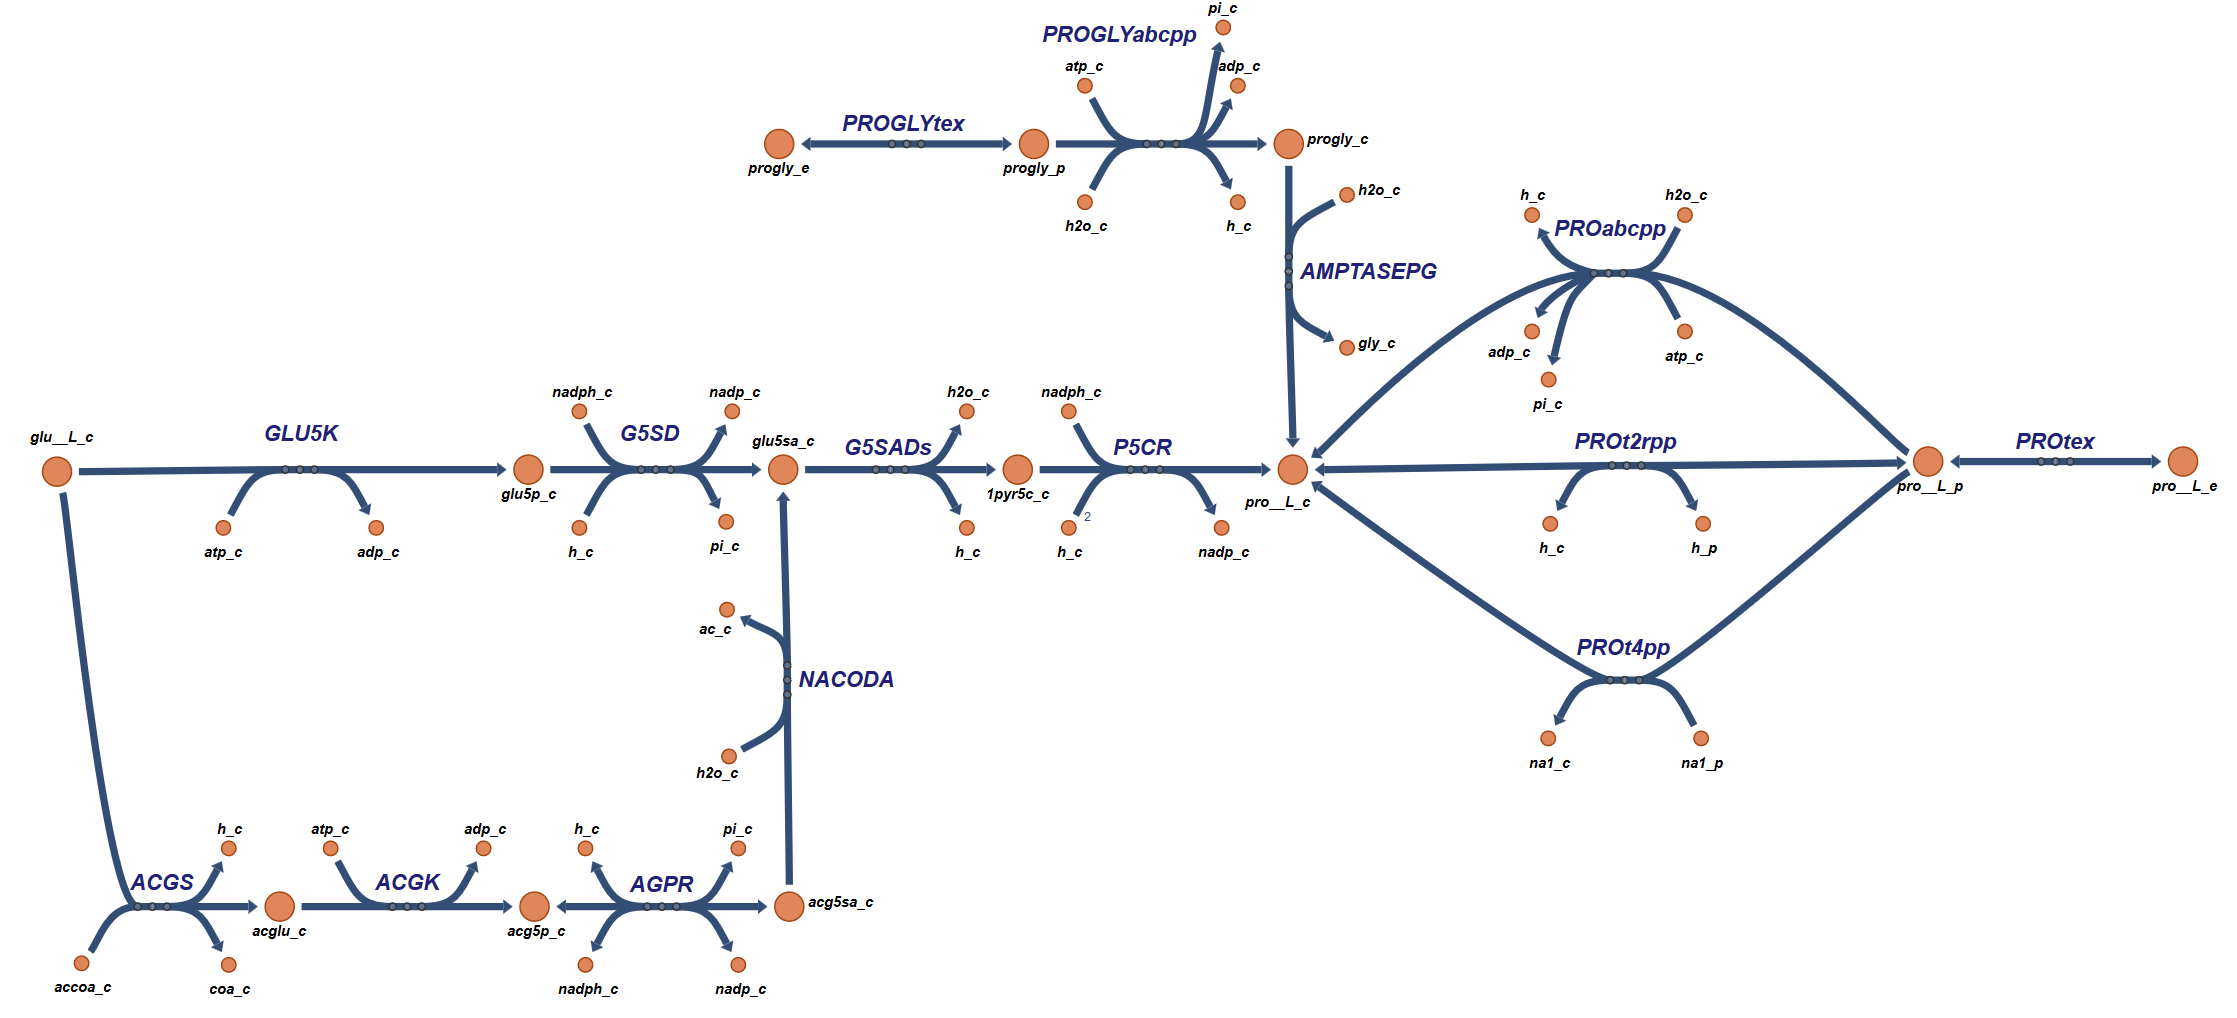

**Figure xx.** Biosynthesis pathways for L-proline.

Let's look at the aerobic response of all these reactions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
prolineReactions = transpose({'AMPTASEPG','GLU5K','G5SD','G5SADs','P5CR','PROabcpp','PROt2rpp','PROt4pp','PROGLYabcpp',...
    'PROtex','PROGLYtex','ACGS','ACGK','AGPR','NACODA'});
[tmp,prolineReactions_rxnID] = ismember(prolineReactions,model.rxns);
printLabeledData(prolineReactions, round(FBAsolution.x(prolineReactions_rxnID),3))

AMPTASEPG	0	
GLU5K	0.217	
G5SD	0.217	
G5SADs	0.217	
P5CR	0.217	
PROabcpp	0	
PROt2rpp	0	
PROt4pp	0	
PROGLYabcpp	0	
PROtex	0	
PROGLYtex	0	
ACGS	0.291	
ACGK	0.291	
AGPR	-0.291	
NACODA	0	


In this case, it can be seen that only the primary pathway is be used, while the secondary pathway is blocked since 'NACODA' has zero flux. The flux through 'ACGS', 'ACGK', and 'AGPR' is path of teh L-Arginine pathway.

**L-Arginine**

Following the process that was outlined in the section on L-Proline we can identify the reactions that create the L-Arginine biosynthesis pathways. The reactions include 'ACGS', 'ACGK', 'AGPR', 'ACOTA', 'ACODA', 'OCBT', 'CBPS', 'ARGSS', 'ARGSL', 'ARGabcpp', 'ARGAGMt7pp', 'ARGORNt7pp', and 'ARGtex' as shown in the figure below.

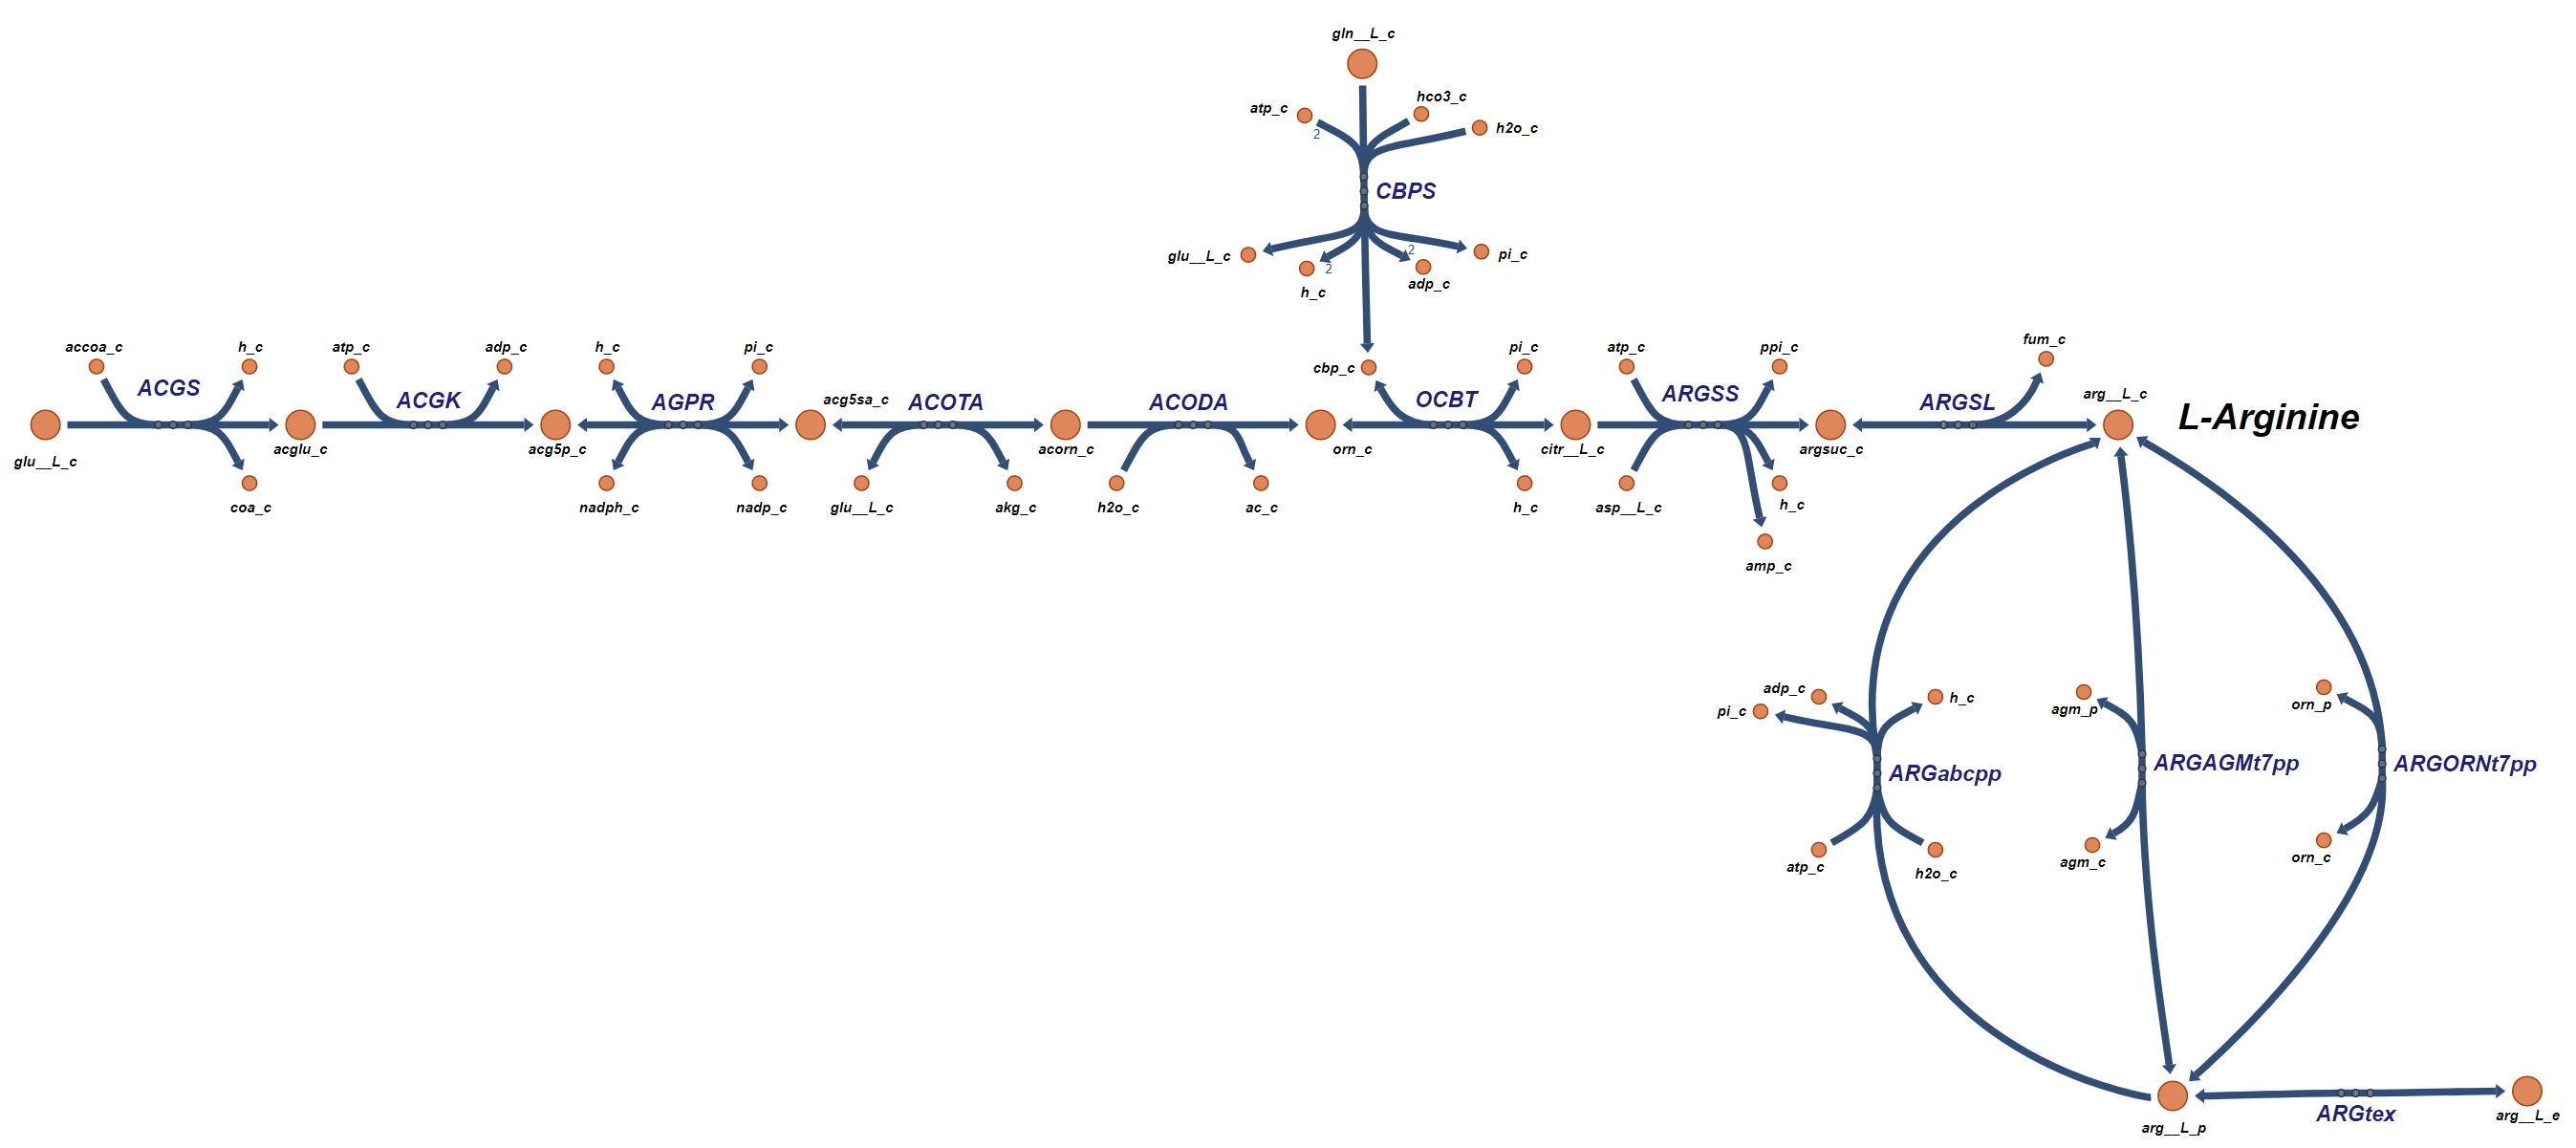

**Figure xx.** L-Arginine biosynthesis pathway.

model = saved_model;
arginineReactions = transpose({'ACGS','ACGK','AGPR','ACOTA','ACODA','OCBT','CBPS','ARGSS','ARGSL','ARGabcpp','ARGAGMt7pp','ARGORNt7pp','ARGtex'});
[tmp,arginine_rxnID] = ismember(arginineReactions,model.rxns);
reactionNames = model.rxnNames(arginine_rxnID);
reactionFormulas = printRxnFormula(model,arginineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',arginineReactions)

T = 13×2 table
                                            reactionNames                                                                reactionFormulas                                  
                  _________________________________________________________________    ____________________________________________________________________________________

    ACGS          'N-acetylglutamate synthase'                                         'accoa_c + glu__L_c  -> acglu_c + coa_c + h_c '                                     
    ACGK          'Acetylglutamate kinase'                                             'acglu_c + atp_c  -> acg5p_c + adp_c '                                              
    AGPR          'N-acetyl-g-glutamyl-phosphate reductase'                            'acg5sa_c + nadp_c + pi_c  <=> acg5p_c + h_c + nadph_c '                            
    <

Let's look at the aerobic response of these reactions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(arginineReactions, round(FBAsolution.x(arginine_rxnID),3))

ACGS	0.291	
ACGK	0.291	
AGPR	-0.291	
ACOTA	-0.291	
ACODA	0.291	
OCBT	0.291	
CBPS	0	
ARGSS	0.291	
ARGSL	0.291	
ARGabcpp	0	
ARGAGMt7pp	-0	
ARGORNt7pp	-0	
ARGtex	0	


Flux variability analysis on 'ARGSL'. 

[minFlux, maxFlux] = fluxVariability(model, 100, 'max', {'ARGSL'})

Starting parallel pool (parpool) using the 'local' profile ...
connected to 12 workers.


minFlux = 0.2906

maxFlux = 0.2906

The maximum production of L-Aginine through 'ARGSL'  is calculated through robustness analysis

Robustness analysis in progress ...
1%      [                                        ]2%      [                                        ]3%      [.                                       ]4%      [.                                       ]5%      [..                                      ]6%      [..                                      ]7%      [..                                      ]8%      [...                                     ]9%      [...                                     ]10%     [....                                    ]11%     [....                                    ]12%     [....                                    ]13%     [.....                                   ]14%     [.....                                   ]15%     [......                                  ]16%     [......                                  ]17%     [......                                  ]18%     [.......                                 ]19%     [.......                                 ]20%     [.....

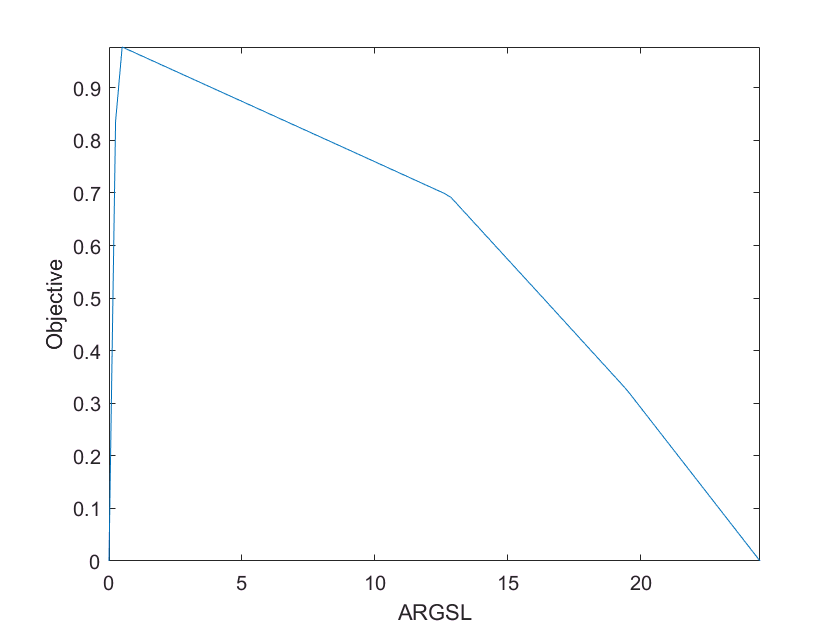

[controlFlux, objFlux] = robustnessAnalysis(model,'ARGSL',100);

## 5. Conclusion

This wraps up the tutorial on the *E.coli* core model. It has attempted to show how the COBRA toolbox can be used to explore a genome-scale metabolic network reconstruction using the core model as an example. Now with this beginning skill set you can start exploring the larger and more accurate network reconstructions!

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Orth, Fleming, and Palsson (2010), *EcoSal Chapter 10.2.1 - Reconstruction and Use of Microbial Metabolic Networks: the Core* Escherichia coli *Metabolic Model as an Educational Guide*  - [http://www.asmscience.org/content/journal/ecosalplus/10.1128/ecosalplus.10.2.1#backarticlefulltext](http://www.asmscience.org/content/journal/ecosalplus/10.1128/ecosalplus.10.2.1#backarticlefulltext)

- Becker, S. et al., ["Quantitative prediction of cellular metabolism with constraint-based models: The COBRA Toolbox"](http://www.nature.com/nprot/journal/v2/n3/full/nprot.2007.99.html), *Nat. Protoc* **2**, 727-738 (2007). 

- Schellenberger J, Que R, Fleming RMT, Thiele I, Orth JD, Feist AM, Zielinski DC, Bordbar A, Lewis NE, Rahmanian S et al., [Quantitative prediction of cellular metabolism with constraint-based models: the COBRA Toolbox v2.0](http://www.ncbi.nlm.nih.gov/pubmed/21886097?dopt=Abstract) *Nat Protoc* **6**(9):1290-307 (2011).

- Feist, A. M., Herrgard, M. J., Thiele, I., Reed , J . L., and Palsson, B. 0., (2009). Reconstruction of biochemical networks in microorganisms. Nat. Rev Microbiol 7 : 129-143. 

- Price, N. D., Papin, J . A., Schilling, C. H. , and Palsson, B. 0., (2003) Genome-scale microbial *in silico* models: the constraints-based approach. Trends Biotechnol 21:162-169.

- Orth, J. D., I. Thiele, et al. (2010). "What is flux balance analysis?" Nature biotechnology 28(3): 245-248. 

- Schellenberger, J., Park, J. O., Conrad, T. M., and Palsson, B. O., (2010) ["BiGG: a Biochemical Genetic and Genomic knowledgebase of large scale metabolic reconstructions"](http://www.biomedcentral.com/1471-2105/11/213), *BMC Bioinformatics*, **11**:213, (2010).

- King, Z.A., Lu, J., Draeger, A., Miller, P., Federowicz, S., Lerman, J.A., Palsson, B.O., Lewis, N.E., (2015)  ["BiGG models: A platform for integrating, standardizing and sharing genome-scale models"](http://nar.oxfordjournals.org/content/early/2015/10/15/nar.gkv1049.long), *Nucleic Acids Research* (2015)

- Schaechter, M., Ingraham, J. L., Neidhardt, F. C. (2006), "Microbe", ASM Press, Washington, D. C.

- Edwards, J. S. and B. O. Palsson (2000). "Robustness analysis of the Escherichia coli metabolic network." Biotechnology progress 16(6): 927-939.

- M. Schaechter et al, "Microbe", ASM Press, 2006, p.119.

- D. White, "The physiology and biochemistry of prokaryotes," 3rd edition, Oxford University Press, 2007.